## **Matrix Techniques**

**Create a matrix x**

x = [ 1 2 3; 4 5 6; 7 8 9]

**Create a matrix y**

y = ones(3,3)

**Now we can concat them horizontally by doing either of the following:**

z = [x,y]

z1 = [y,x]

**Vertical concat is like so:**

v = [x;y]

v1 = [y;x]

## **Complex Numbers**

**How to represent and use complex numbers:**

x = sqrt(-1)
y = sqrt(-2)
z = x + y

## Array Indexing

**Create a 5x5 array**

M = magic(5)

**To find what is in row 1 col 4**

x = M(1,4)

**Row 2 col 1 is**

x2 = M(2,1)

**If you go out of range, you will get an error for out of bounds**

%% x3 = M(6,1)

**To access multiple cols for a row**

v = M(2, 1:5)

## **Saving and loading variables**

You can use command 

% save myvar.mat
% load myvar.mat

## **Plotting 2D Graphs**

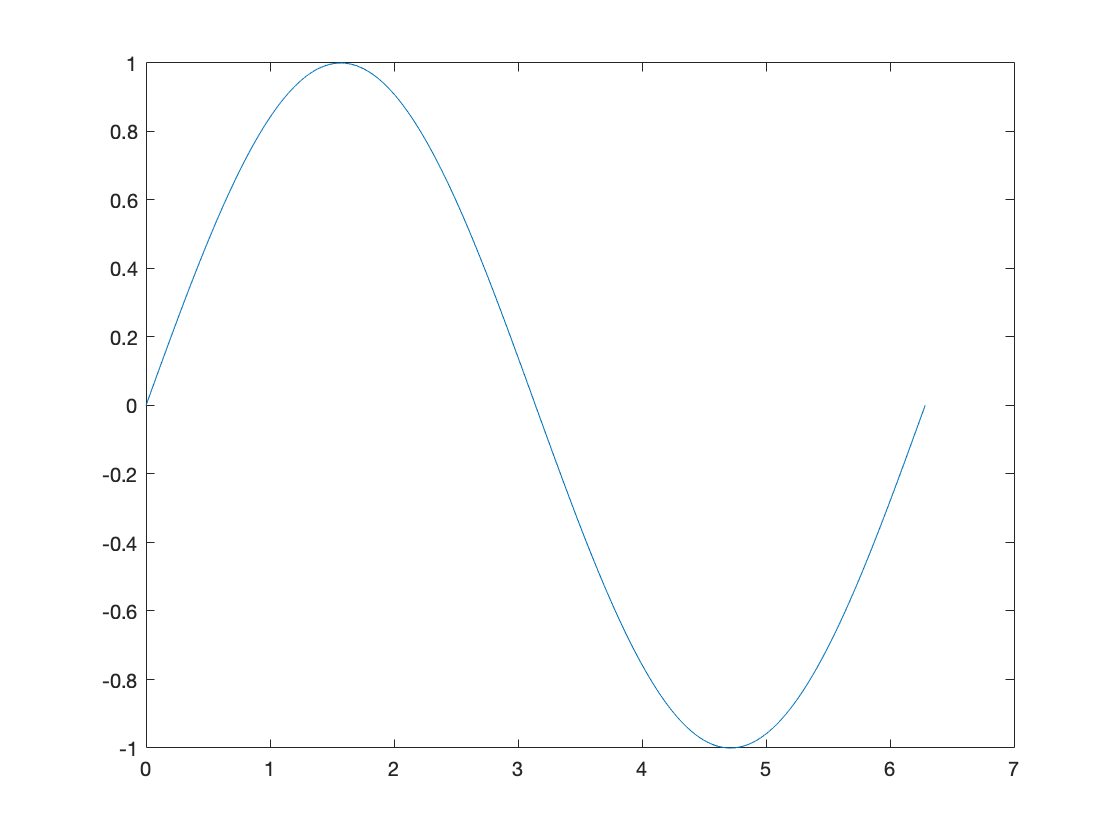

x = 0 : pi/100 : 2*pi;
y = sin(x);
plot(x,y)

**Plotting Multiple graphs will be like so:**

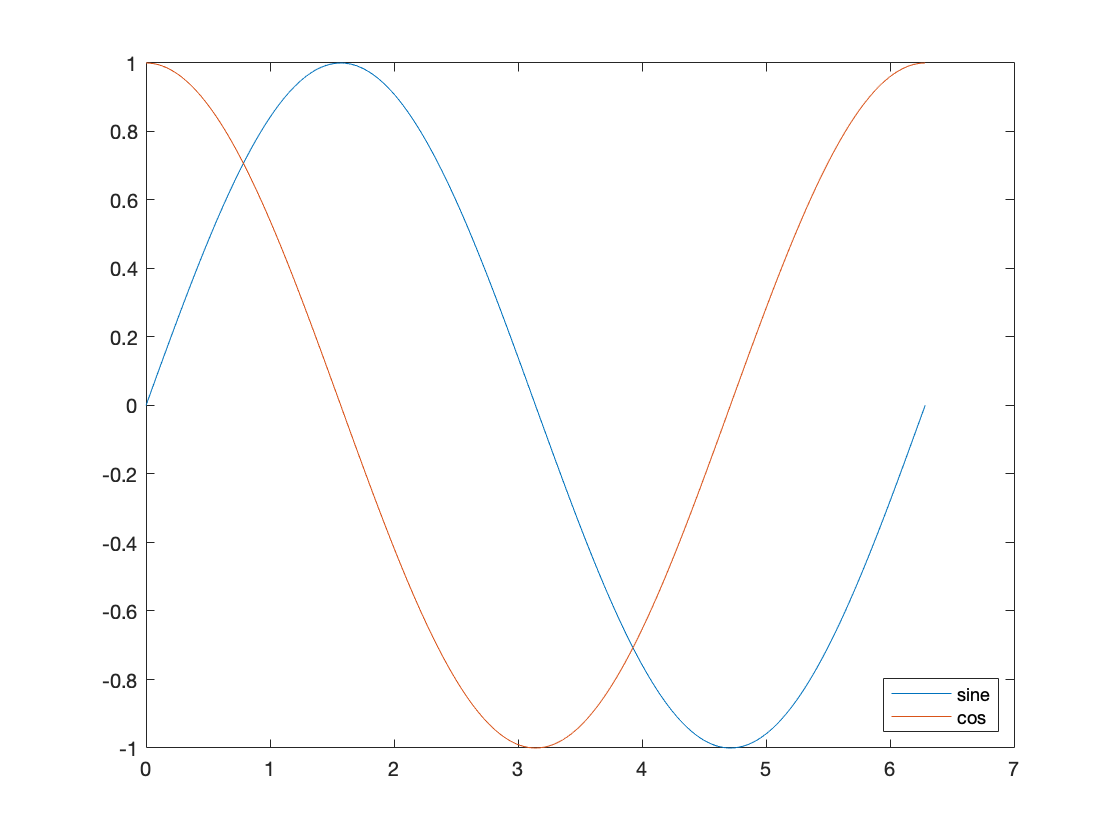

plot(x,y)
hold on
y2 = cos(x);
plot(x,y2)
legend('sine','cos', 'Location', 'southeast')
hold off

## **Handle Missing Data**

x = [1 2 3 NaN 6 7 8]

x =      1     2     3   NaN     6     7     8


**You can also create missing data using 'missing'**

y = [10 11 12 13 missing 89]

y =     10    11    12    13   NaN    89


**If you try calculating the mean of x, you will get NaN**

mean(x)

ans =    NaN


**One way matlab handles this is by grabbing the max and min of x**

max(x)

ans =      8


min(x)

ans =      1


**You can check by using the function isnan(), where the argument is the array in question, 1 is true and 0 is false**

isnan(x)

ans = 1×7 logical array
   0   0   0   1   0   0   0


**You can set with commands below**

x

x =      1     2     3   NaN     6     7     8


x2 = fillmissing(x, 'constant', 1)

x2 =      1     2     3     1     6     7     8


**Now we can conduct calculations and plot with this array now**

std(x2)

ans =    2.943920288775949


var(x2)

ans =    8.666666666666666


**You can also just remove the missing data**

x3 = rmmissing(x)

x3 =      1     2     3     6     7     8


## **Reading and writing to files**

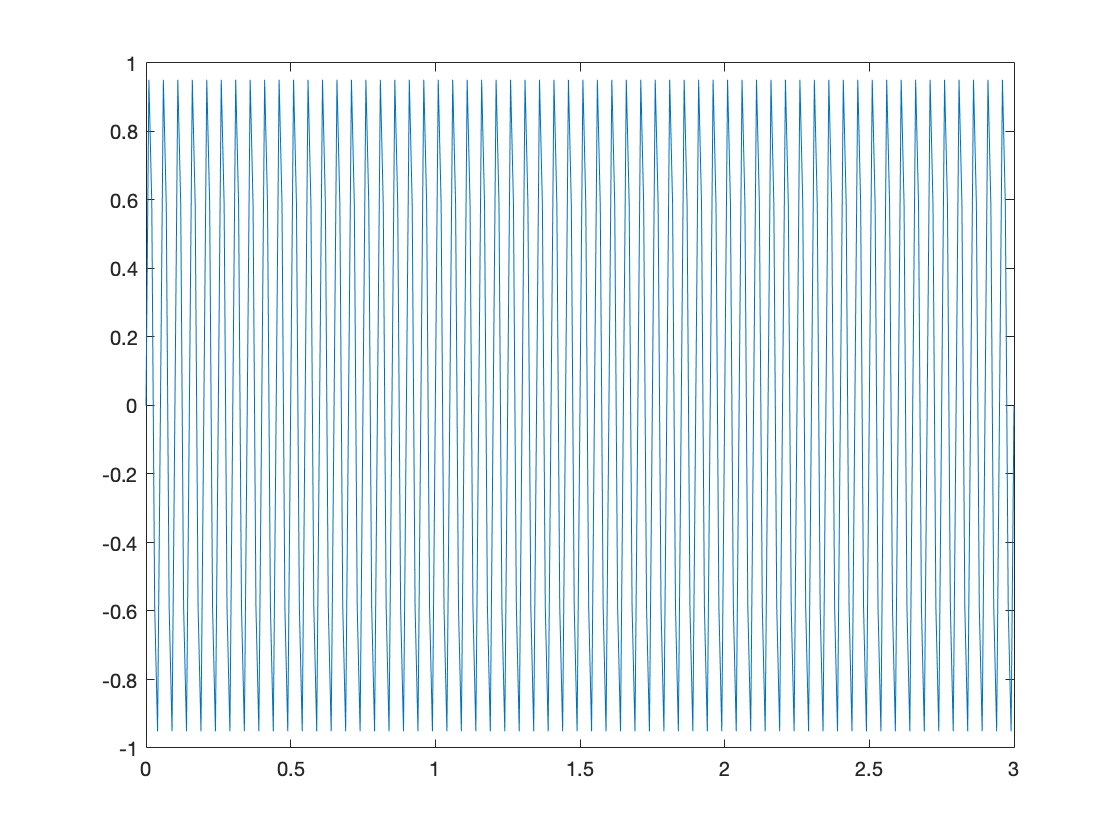

f = 20; % 20 Hz signal
ts = 1/100; % Time step of 1/100 s
T = 3; % Max time of 3s
t = 0 : ts : T; % Set the time interval
y = sin(2*pi*f*t);
plot(t,y)

**Now we are going to write this to a file**

csvwrite('_simple_signal.txt', y);

**We shall now read from the file**

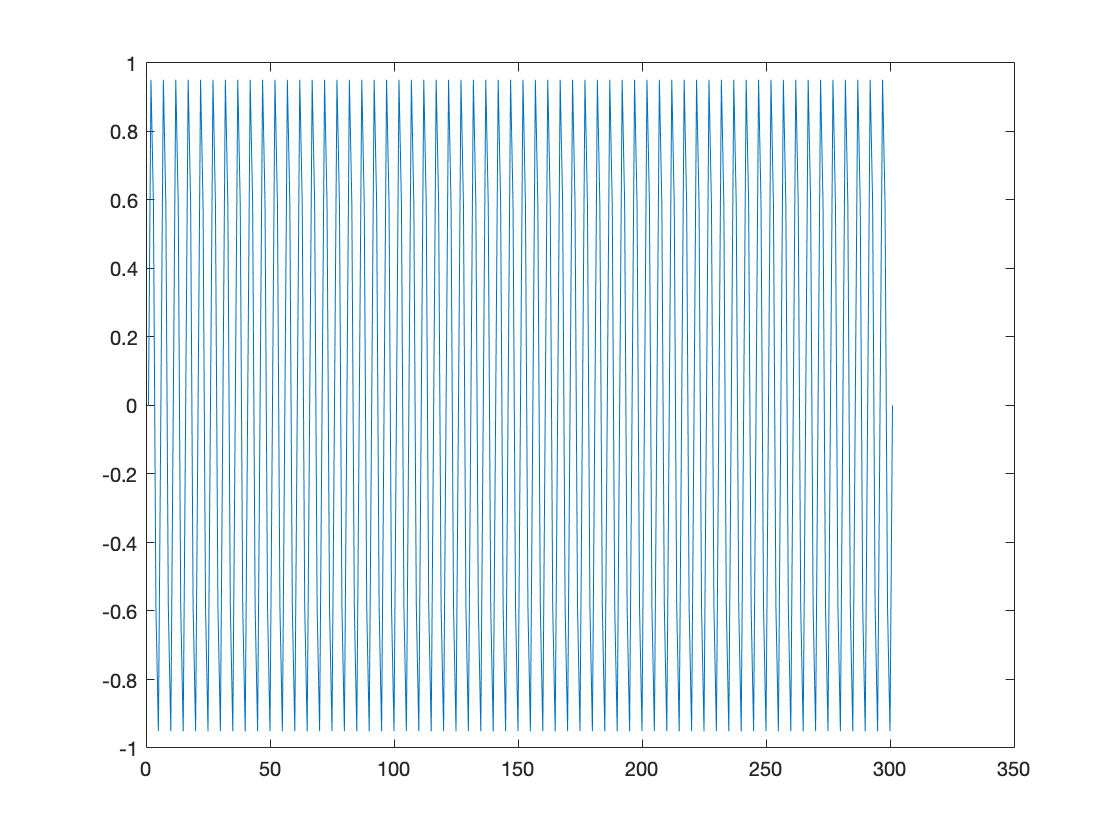

clear;
signal = load('_simple_signal.txt');
plot(signal);

**We can also read using csvread**

signal2 = csvread('_simple_signal.txt');
plot(signal2)